# Frenet参照経路を用いた高速道路軌道計画

この例は、高速道路走行シナリオにおけるローカル軌道の計画方法を示す。本例では、基準経路と動的障害物リストを用いて、自己車両の代替軌道を生成します。自己車両は、drivingScenarioオブジェクトから提供される走行シナリオで定義された交通状況を通過します。車両は、コスト、実現可能性、衝突回避運動に基づき、適応型クルーズ制御、車線変更、追従走行を交互に実行します。

## Driving Scenario の読み込み

まず、提供されたdrivingScenarioオブジェクトを読み込みます。このオブジェクトは、現在のワークスペースにおける車両と道路のプロパティを定義します。

このシナリオは [**Driving Scenario Designer**](docid:driving_ref#mw_07e6310f-b9c9-4f4c-b2f9-51e31d407766) アプリを使用して生成され，MATLAB関数の`drivingScenarioTrafficExample にエクスポートされました`.

 For more information, see [Create Driving Scenario Variations Programmatically](docid:driving_ug#mw_2282a3a3-f2b9-4a03-9638-ae7d5b20f8d8).

**下記，関数を呼び出してシナリオを作り、その結果を **`scenario`** に代入**

scenario = SDpaper_scenario1_test;

**下記，シナリオ内で使う車両や道路の「サイズ」を定義して、最後に描画**

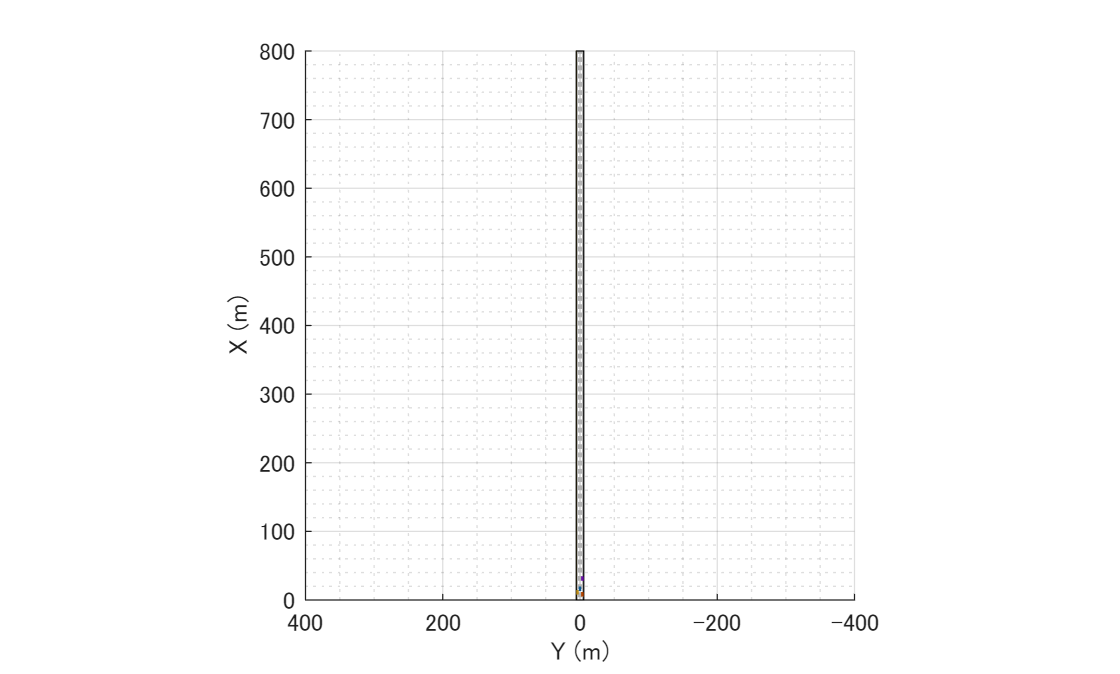

% デフォルトの車両プロパティ
carLen   = 4.7; % [m] 一般的な乗用車の全長
carWidth = 1.8; % [m] 一般的な乗用車の全幅
rearAxleRatio = .25; % 全長 4.7 m なら、後軸は後端から 1.175 m (4.7 × 0.25) の位置にある、という意味。

% Define road dimensions
laneWidth   = carWidth*2; % [m] 車線幅

plot(scenario);

## 参照経路の構築

`この例におけるすべてのローカル計画は `[`referencePathFrenet`](docid:nav_ref#mw_635246b1-0e68-43b2-9cca-062a734a858a)` オブジェクトで表される参照経路に対して実行されます。` このオブジェクトは、パス上の指定された長さにおける曲線の状態を返すことができ、グローバルなxy座標位置に最も近いパス上の点を見つけ、グローバル座標系とフレネ座標系間の座標変換を容易にします。 

この例では、基準経路は4車線道路の中心として扱われ、ウェイポイントは提供されたdrivingScenarioオブジェクトで定義された道路と一致します。

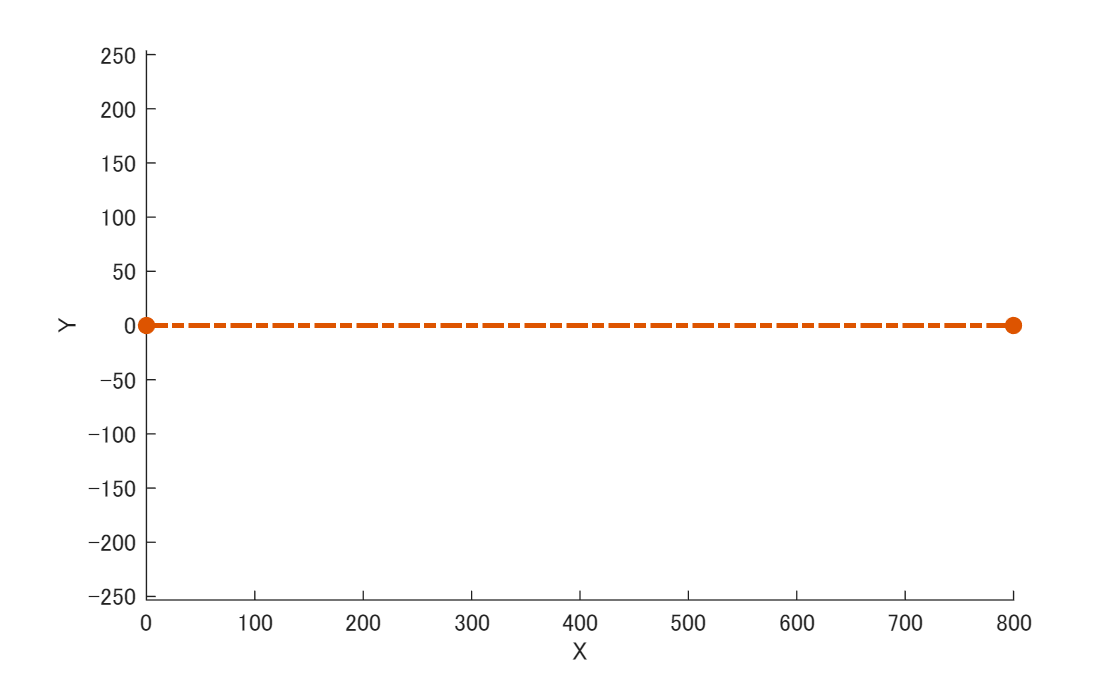

waypoints = [0 0; 800 0]; % [m]
refPath = referencePathFrenet(waypoints); % referencePathFrenet は Frenet座標系用の基準経路オブジェクトを作る関数
ax = show(refPath); % ウェイポイントをつないだ基準経路をプロット
axis(ax,'equal'); xlabel('X'); ylabel('Y'); % X軸とY軸のスケールを揃えて、正しい形で表示

refPath = referencePathFrenet(waypoints); のよるオブジェクトを作ると

- 任意の点の「弧長 s」と「横オフセット l」を計算できる

- 車両の状態 (X,Y,θ) を Frenet座標に変換できる

- 軌道生成・衝突判定の基準として使える

## 軌道生成器の構築

局所計画者にとっての目標は、通常、現在の運動学的・力学的条件を満たしつつ最終目標に向かって進む様々な可能な運動をサンプリングすることである。 The [`trajectoryGeneratorFrenet`](docid:nav_ref#mw_e10117a7-ee2f-4161-92aa-9d378742b27c)` オブジェクトは`初期状態と一連の終端状態を4次または5次の多項式軌道を用いて接続することでこれを実現する。 初期状態と終端状態はフレネ座標系で定義され、各多項式解は横方向および縦方向の位置、速度、加速度の境界条件を満たしつつ、ジャークを最小化する。

終端状態は、カスタム動作を用いて計算されることが多い。これらの動作は、車線情報、速度制限、自己車両周辺のアクターの現在または将来の予測など、ローカル環境で検出された情報を活用する。

参照経路を用いてtrajectoryGeneratorFrenetオブジェクトを構築する

 **下記，Frenet座標系で軌道を生成する「ジェネレータ（生成器=connector）」を作る処理 **

connector = trajectoryGeneratorFrenet(refPath);

`trajectoryGeneratorFrenet` は **Frenet基準経路上で軌道を生成するオブジェクト** を作成する関数

## 動的衝突チェッカーの構築

The [`dynamicCapsuleList`](docid:nav_ref#mw_7adae6fc-28a4-49cf-9120-4a0b7c6bce23)` オブジェクトは、離散的な時間ステップの集合にわたる動的環境の状態を表すデータ構造です。この環境は、自己車両の複数の潜在的な軌道を効率的に検証するために使用できます。シーン内の各オブジェクトは以下によって表されます`

- 一意な整数値の識別子

- 効率的な衝突判定に使用されるカプセル形状のプロパティ

- SE2状態のシーケンス。各状態は時間における個別のスナップショットを表す。

この例では、trajectoryGeneratorFrenetオブジェクトによって生成される軌道は、時間地平線と呼ばれる一定期間にわたって発生します。衝突チェックがすべての可能な軌道を確実にカバーするためには、dynamicCapsuleListオブジェクトには、最大予想時間地平線にわたる全アクターの予測軌道が含まれている必要があります。

**下記，**`dynamicCapsuleList`** は、動的な車両や障害物を「カプセル（楕円状の当たり判定）」で表すためのリストオブジェクト を作成する関数**

dynamicCapsuleListオブジェクトとはカプセルベースの衝突オブジェクトの二つのリストを管理する

衝突オブジェクト：エゴボディ＆障害物

二つのリスト内の各オブジェクトには3つの重要な要素が存在

- **ID**：各オブジェクトを識別する整数。`EgoIDs`自我体のプロパティと `ObstacleIDs`障害物のプロパティに保存されます

- **状態**：オブジェクトの位置と向きを*M*行3列の行列で表します。各行は の形式で`[x y theta]，`*Mは*ワールドフレームにおけるオブジェクトの軌跡上の状態の数

- **ジオメトリ**：

`capList` → 衝突判定用の **dynamicCapsuleList**

capList = dynamicCapsuleList;

#### 自車について

与えられたパラメータを用いて、自己車両の幾何構造を作成する。

egoID = 1; % 自車両には「1」を割り振り，dynamicCapsuleList に登録する車両を一意に識別する番号
[egoID, egoGeom] = egoGeometry(capList,egoID); % dynamicCapsuleList（capList）内で、ID=1 の Ego 車両用の ジオメトリ情報を取り出します。

egoGeom.Geometry.Length = carLen; % 4.7 [m]
egoGeom.Geometry.Radius = carWidth/2; % 1.8/s=0.9 [m]
egoGeom.Geometry.FixedTransform(1,end) = -carLen*rearAxleRatio; % [m], -carLen * 0.25 = -1.175 m を指定すると、カプセルが 後輪軸を基準に配置される

エゴビークルを動的カプセルリストに追加

**下記，Ego 車両の形状を capList に反映する（**Ego 車両のカプセル情報を capList に登録・更新**）**

`この操作の前では，egoGeometry` で取得した `egoGeom` はまだ「ローカル変数」で、capList 自体には反映されていません。

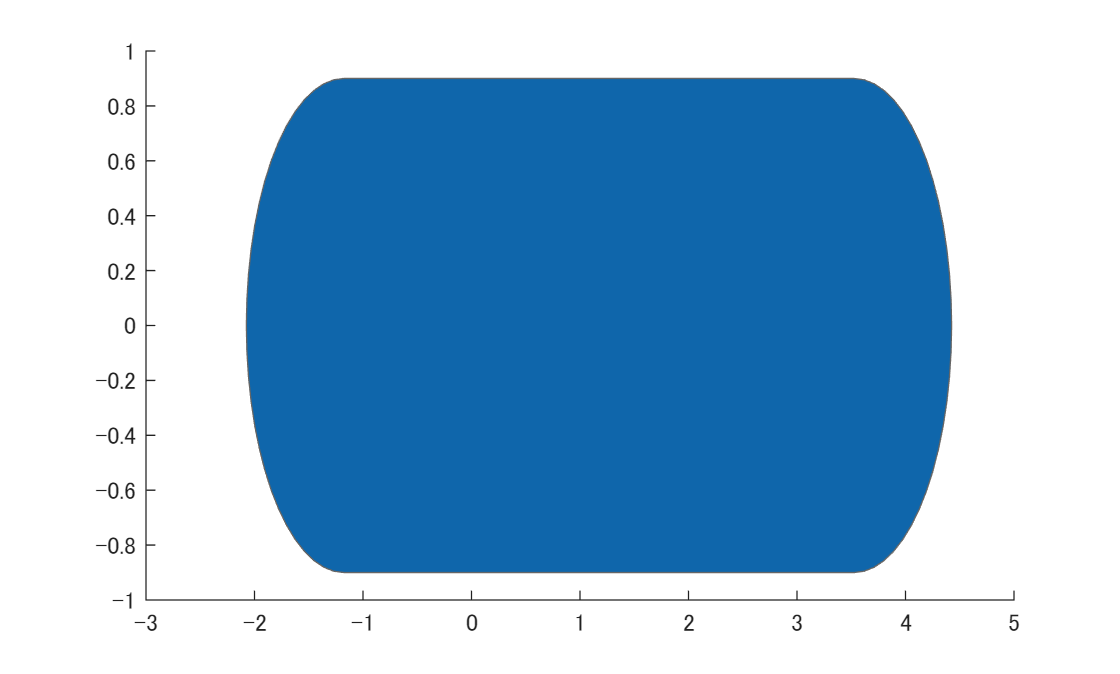

ans =   Axes のプロパティ:

             XLim: [-3 5]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  すべてのプロパティ を表示


updateEgoGeometry(capList,egoID,egoGeom);
show(capList)

### 障害物について

drivingScenarioアクターをdynamicCapsuleListオブジェクトに追加します。ここでジオメトリが設定され、計画ループ中に状態が定義されます。dynamicCapsuleListには現在、自車両1台と障害物5つが含まれていることが確認できます。

**下記，他車両（障害物車両）を **`capList`** に登録する処理**

actorID = (1:3)'; % 他車両（Actor）の ID を 1〜6 の連番で作成。actorID は列ベクトル [1; 2; 3; 4; 5; 6]。
actorGeom = repelem(egoGeom,3,1); % egoGeom → 先ほど定義した 車両の形状（長さ=4.7m, 幅=1.8m, 後輪基準）, repelem(...,5,1) → これを 6台分コピーして、6×1 の構造体配列にする
updateObstacleGeometry(capList,actorID,actorGeom) % capList に「ID=1〜6 の車両」を 障害物（Obstacle）として登録。それぞれの車両は actorGeom に基づいて、長さ4.7m・幅1.8m のカプセルで表される

ans =   dynamicCapsuleList のプロパティ:

     MaxNumSteps: 31
          EgoIDs: 1
     ObstacleIDs: [3×1 double]
    NumObstacles: 3
         NumEgos: 1


## 交通状況に応じた適応ルートの計画

計画ユーティリティは、現在の環境状態と予測される環境状態に基づいて一連の局所軌道をサンプリングし、最も最適な軌道を選択する局所計画戦略をサポートする。シミュレーションループは以下のセクションに構成されている：

- Advance the Ground Truth Scenario

- Generate Terminal States

- Evaluate Cost of Terminal States

- Generate Trajectories and Check for Kinematic Feasibility

- Check Trajectories for Collision and Select the Optimal Trajectory

- Display the Sampled Trajectories and Animate Scene

各セクションのタイトルをクリックすると、シミュレーションループ内の関連するコードに移動します。

### Advance Ground Truth Scenario

動的な環境で計画を立てる場合、環境の状態を推定したり、近い将来の状態を予測したりすることがしばしば必要となります。簡略化のため、この例ではdrivingScenarioを、計画期間における各アクターの軌道のグラウンドトゥルースソースとして使用します。カスタム予測アルゴリズムをテストするには、exampleHelperRetrieveActorGroundTruth関数をカスタムコードで置き換えるか修正することができます。

### Generate Terminal States

自動運転における共通の目標は、計画された軌跡が単に実現可能であるだけでなく、自然なものであることを保証することです。典型的な高速道路走行には、車線維持、制限速度の遵守、車線変更、交通状況に応じた速度調整などの要素が含まれます。それぞれのカスタム動作には異なる環境情報が必要となる場合があります。この例では、クルーズコントロール、車線変更、先行車追従という3つの動作を実現する終端状態を生成する方法を示します。

#### クルーズコントロール

`exampleHelperBasicCruiseControl` 関数は、クルーズコントロール動作を実行する終端状態を生成します。この関数は、自己車両の横方向速度と時間ホライズンを用いて、N秒後の自己車両の予想レーンを予測します。レーン中心が計算され終端状態の横方向偏差となり、横方向速度と加速度はゼロに設定されます。

縦方向境界条件では、終端速度は道路速度制限に設定され、終端加速度はゼロに設定される。縦方向位置は制限されず、NaNとして指定される。経度制約を解除することで、trajectoryGeneratorFrenetはより低次の4次多項式を用いて縦方向境界値問題を解くことができ、これにより与えられた時間範囲内で道路速度に滑らかに適合する軌跡が得られる：


$$cruiseControlState=\left\lbrack \textrm{NaN}\;{\dot{s} }_{des} \ 0\ l_{expLane} \ 0\ 0\right\rbrack$$


#### 車線変更

`exampleHelperBasicLaneChange` 関数は、車両を現在の車線から隣接するいずれかの車線へ移行させる終端状態を生成する。この関数はまず自車の現在の車線を判定し、次に左右両方の車線が存在するかどうかを確認する。存在する各車線について、終端状態はクルーズコントロール動作と同様の方法で定義されるが、終端速度は道路の制限速度ではなく現在の速度に設定される点が異なる：


$$laneChangeState={\left[\textrm{NaN}\;\;{\dot{s} }_{cur} \;\ 0\ l_{desLane} \ 0\ 0\right]}$$


#### 前方車追従

`exampleHelperBasicLeadVehicleFollow` 関数は、自己車両の前方に発見された車両を追従しようとする終端状態を生成する。この関数はまず自己車両の現在の車線を判定する。指定された時間地平線ごとに、各アクターの将来状態を予測し、自己車両と同じ車線を占有する全アクターを検出し、最も近い先行車両を特定する（先行車両が見つからない場合、関数は何も返さない）。

自己車両の終端状態は、先行車両の位置と速度を取得し、終端縦方向位置から安全距離を差し引くことで計算されます：


$$closestLeadVehicl\textrm{eState}=\left\lbrack s_{lead} \ {\dot{s} }_{lead} \ 0\ l_{lead} \ {\dot{l} }_{lead} \ 0\right\rbrack$$



$$\textrm{followState}=\left\lbrack \left(s_{lead} -d_{\textrm{safety}} \right)\ {\dot{s} }_{lead} \ 0\ l_{lead} \ {\dot{l} }_{lead} \ 0\right\rbrack$$


### Evaluate Cost of Terminal States

終端状態が生成された後、それらのコストを評価できる。経路評価と潜在的な解の優先順位付け方法は非常に主観的である。簡略化のため、例として示した`exampleHelperEvaluateTSCost`関数では、コストを3つの重み付き和の組み合わせとして定義している。

- **Lateral Deviation Cost (**$C_{latDev}$**) **— レーン中心から逸脱した状態に課す正の重み。


$$C_{latDev} =w_{\Delta L} *\Delta \mathrm{L}$$



$$\Delta L={\textrm{argmin}}_i \left(\left|L_{\textrm{termState}} \;-L_{{\textrm{lane}}_i } \right|\right)$$


- **Time Cost (**$C_{time}$**) **— より長い間隔で発生する動作を優先する負の重み付けにより、より滑らかな軌跡が得られる。


$$C_{time} =w_{\Delta t} *\Delta t$$


- **Terminal Velocity Cost (**$C_{speed}$**) **— 制限速度を維持する動作を優先する正の重み付けにより、動的な操作が減少する。


$$C_{speed} =w_{\Delta v} *\Delta v$$


### Generate Trajectories and Check for Kinematic Feasibility

最小コストの終端状態に加え、最適軌道は運動学的実現可能性や乗り心地に関する追加制約を満たす必要がある場合が多い。軌道制約は望ましい乗り心地を実現する手段の一つだが、その代償として走行可能領域が縮小される。

この例では、`exampleHelperEvaluateTrajectory` 関数は、各軌道が以下の制約を満たすことを検証します： 

- `MaxAcceleration`: 軌跡全体における絶対加速度は、所定の値以下でなければならない。より小さい値は運転の攻撃性を低減し、運動学的に不可能な軌跡を排除する。この制限により、本来なら車両が実行可能な操作が排除される場合がある。

- `MaxCurvature`: 軌跡全体で許容される最小旋回半径。最大加速度と同様に、この値を小さくすると運転体験は滑らかになるが、本来実現可能な軌跡が排除される可能性がある。

- `MinVelocity`: この例では、最小速度を設定することでエゴビークルを前方方向のみの運動に制限する。この制約は高速道路走行シナリオで望ましく、過度に制約された境界値や条件の悪い境界値に適合する軌道を排除する。

### Check Trajectories for Collision and Select Optimal Trajectory

計画プロセスの最終段階は、衝突のない経路も実現する最適な軌道を選択することである。衝突チェックは計算コストが高いため、しばしば最終段階まで延期される。したがって、まずコスト評価と制約分析を行うことで、無効な軌道を検討対象から除外できる。その後、残った軌道を最適な順序で衝突チェックし、衝突のない経路が見つかるか、全ての軌道の評価が完了するまで処理を続ける。

## シミュレータと計画パラメータの定義

このセクションでは、シミュレータの実行に必要なプロパティと、プランナおよび行動ユーティリティで使用されるパラメータを定義します。`scenario.SampleTime`や`connector`.`TimeResolution`などのプロパティは同期され、グラウンドトゥルースアクタの軌跡と計画されたエゴ軌跡の状態が同一のタイムステップで発生するように調整されます。同様に、`replanRate`, `timeHorizons`, `maxHorizon`は、シミュレーションレートに対する整数倍となるように選択されます。

前節で述べたように、重量と制約は、道路規則を遵守しつつ滑らかな走行軌跡を促進するように選択される。

最後に、速度制限（`speedLimit`）と安全距離（`safetyGap`）パラメータを定義します。これらはプランナーの終端状態を生成するために使用されます。

% シミュレータの更新レートを軌道生成器の離散化間隔に合わせるように同期する。
% scenario.SampleTime → シナリオのシミュレーション刻み時間
% connector.TimeResolution → Frenet軌道生成器が使う時間刻み
% これを揃えることで、軌道生成とシナリオ進行を同じタイミングで動かすことができる。
scenario.SampleTime = connector.TimeResolution; % in seconds


% 計画パラメータを定義する。
% 10 Hz = 0.1秒ごとに軌道を再計算。
replanRate = 10; % Hz

% 現在の状態と計画状態の間隔を定義する。
timeHorizons = 1:1:4; % [sec] 各候補軌道を「1秒先まで」「2秒先まで」「3秒先まで」と生成し、評価する。
maxHorizon = max(timeHorizons); % [sec]  maxHorizon = 3 秒が最大計画範囲。

% コストパラメータの定義
latDevWeight    =  1; % 横方向ずれ（車線中央からの逸脱）
timeWeight      =  -1; % 短い時間を好む
speedWeight     =  1; % 目標速度からの逸脱

% 以下の制約に違反する軌道を排除する。
maxAcceleration =  15; % [m/s^2] 車両が出せる最大加速度を超えたら不適
maxCurvature    = 100; % [1/m], or [rad/m] 最小旋回半径 ≈ 1m
minVelocity     =   0; % [m/sec] 負の速度（バック）や停止を避ける。

% クルーズコントロール動作および軌道コスト評価時に使用される目標速度設定値。
speedLimit = 18; % [m/sec] 巡航時の目標速度。コスト評価の基準値

% プランナーが追従動作において目標とする最小距離。
safetyGap = 72; % [m] 前車との最低距離。これを下回る軌道は不適切として棄却

## シミュレータの初期化

シミュレータを初期化し，[`chasePlot`](docid:driving_ref#bvna0wv)ビューアを作成する。

この関数は「軌道計画 + 衝突判定シミュレーション」を回すための**初期設定**をまとめてやってくれる

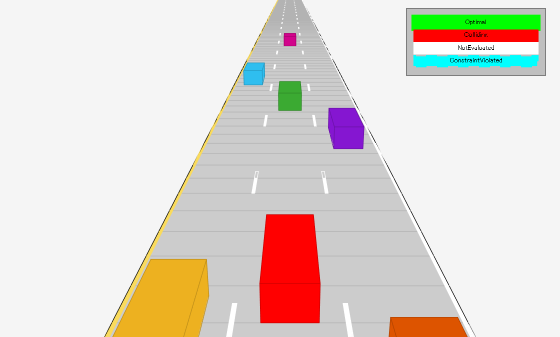

[scenarioViewer,futureTrajectory,actorID,actorPoses,egoID,egoPoses,stepPerUpdate,egoState,isRunning,lineHandles] = exampleHelperInitializeSimulator(scenario,capList,refPath,laneWidth,replanRate,carLen);

返り値の意味 

- `scenarioViewer：`Ego車両や他車両、基準経路や将来軌道をアニメーション表示するのに使われます

- futureTrajectory：Ego車両の将来の計画軌道を保持するデータ構造，Frenet軌道生成器で出た候補を格納し、アニメーション時に描画するために利用

-  `actorID：capList` に登録した actor の ID をここに集約

- actorPoses：他車両の 初期位置・姿勢（x,y,θ,v）リスト，シミュレーション中に更新されていきます

- egoID：Ego車両の ID（通常は 1），`capList` 内で Ego 車両を識別するのに使います

- egoPoses：Ego車両の初期位置・姿勢，後で AMPC 追従や軌道生成のスタート状態に使われます

- stepPerUpdate：軌道再計画の周期を **シナリオのステップ数**で表した値。例えばシナリオの刻みが 0.01 s、再計画周期が 0.1 s なら → `stepPerUpdate = 10`。「何ステップ進めたら軌道を更新するか」を決めます。

- egoState：Ego車両の 現在状態，軌道生成の「始点」として使われます。

- isRunning：シミュレーションが **まだ続行中かどうか**（true/false），メインループの終了条件に使われます。

- lineHandles：軌道、車両の位置、将来予測などをプロットする線を格納。毎回 `plot` し直す代わりに、ハンドルを更新してアニメーションを効率化します。

## 運転シミュレーションの実行

tic % MATLAB の経過時間計測をスタート
while isRunning
    % アクター車両の現在の状態と計画ホライズンにわたる軌跡を取得する。
    [curActorState,futureTrajectory,isRunning] = ...
        exampleHelperRetrieveActorGroundTruth(scenario,futureTrajectory,replanRate,maxHorizon);

    % 巡航制御の状態を生成
    [termStatesCC,timesCC] = exampleHelperBasicCruiseControl(...
        refPath,laneWidth,egoState,speedLimit,timeHorizons);
    
    % 車線変更の状態を生成
    [termStatesLC,timesLC] = exampleHelperBasicLaneChange(...
        refPath,laneWidth,egoState,timeHorizons);
    
    % 前方車追従の状態を生成
    [termStatesF,timesF] = exampleHelperBasicLeadVehicleFollow(...
        refPath,laneWidth,safetyGap,egoState,curActorState,timeHorizons);


       



        % 終端状態をまとめる
    labels = [repmat("Cruise", size(termStatesCC,1), 1); 
              repmat("LaneChange", size(termStatesLC,1), 1);
              repmat("Follow", size(termStatesF,1), 1)];
    allTS   = [termStatesCC; termStatesLC; termStatesF];
    allTime = [timesCC; timesLC; timesF];

    % テーブル形式にする（全6成分を列に展開）
    T = table(labels, allTime, ...
        allTS(:,1), allTS(:,2), allTS(:,3), allTS(:,4), allTS(:,5), allTS(:,6),...
        'VariableNames', {'Behavior','Horizon','S','dS','ddS','L','dL','ddL'});

    disp(T);

      Behavior      Horizon     S     dS    ddS     L      dL    ddL
    ____________    _______    ___    __    ___    ____    __    ___

    "Cruise"           1       NaN    18     0        0    0      0 
    "Cruise"           2       NaN    18     0        0    0      0 
    "Cruise"           3       NaN    18     0        0    0      0 
    "Cruise"           4       NaN    18     0        0    0      0 
    "LaneChange"       1       NaN    22     0     -3.6    0      0 
    "LaneChange"       2       NaN    22     0     -3.6    0      0 
    "LaneChange"       3       NaN    22     0     -3.6    0      0 
    "LaneChange"       4       NaN    22     0     -3.6    0      0 
    "LaneChange"       1       NaN    22     0      3.6    0      0 
    "LaneChange"       2       NaN    22     0      3.6    0      0 
    "LaneChange"       3       NaN    22     0      3.6    0      0 
    "LaneChange"       4       NaN    22     0      3.6    0      0 

      Behavior      Horizon     

    % 終端状態と時間を組み合わせる。
    allTS = [termStatesCC; termStatesLC; termStatesF];
    allDT = [timesCC; timesLC; timesF];
    numTS = [numel(timesCC); numel(timesLC); numel(timesF)];
    
    % すべての終端状態のコストを評価する。
    costTS = exampleHelperEvaluateTSCost(allTS,allDT,laneWidth,speedLimit,...
        speedWeight, latDevWeight, timeWeight);

    % 軌道を生成
    egoFrenetState = global2frenet(refPath,egoState);
    [frenetTraj,globalTraj] = connect(connector,egoFrenetState,allTS,allDT);
    
    % 制約条件に違反する軌道を排除
    isValid = exampleHelperEvaluateTrajectory(globalTraj,maxAcceleration,maxCurvature,minVelocity);
    % disp(isValid);

    % シーン内の全アクターの予測軌道を衝突チェッカーに反映させる。
    for i = 1:numel(actorPoses)
        actorPoses(i).States = futureTrajectory(i).Trajectory(:,1:3);
    end
    updateObstaclePose(capList,actorID,actorPoses);
    
    % 評価順序を決定する。
    [cost, idx] = sort(costTS);
    optimalTrajectory = [];
    
    trajectoryEvaluation = nan(numel(isValid),1);
    
    % 最小コストから順に、各軌道の衝突をチェックする。
    for i = 1:numel(idx)
        if isValid(idx(i))
            % エゴオブジェクトの候補軌道でカプセルリストを更新する。
            egoPoses.States = globalTraj(idx(i)).Trajectory(:,1:3);
            updateEgoPose(capList,egoID,egoPoses);
            
            % 衝突をチェックする。
            isColliding = checkCollision(capList);
            
            if all(~isColliding)
                % 衝突が検出されない場合、これが最適軌道である。
                trajectoryEvaluation(idx(i)) = 1;
                optimalTrajectory = globalTraj(idx(i)).Trajectory;
                break;
            else
                trajectoryEvaluation(idx(i)) = 0;
            end
        end
    end

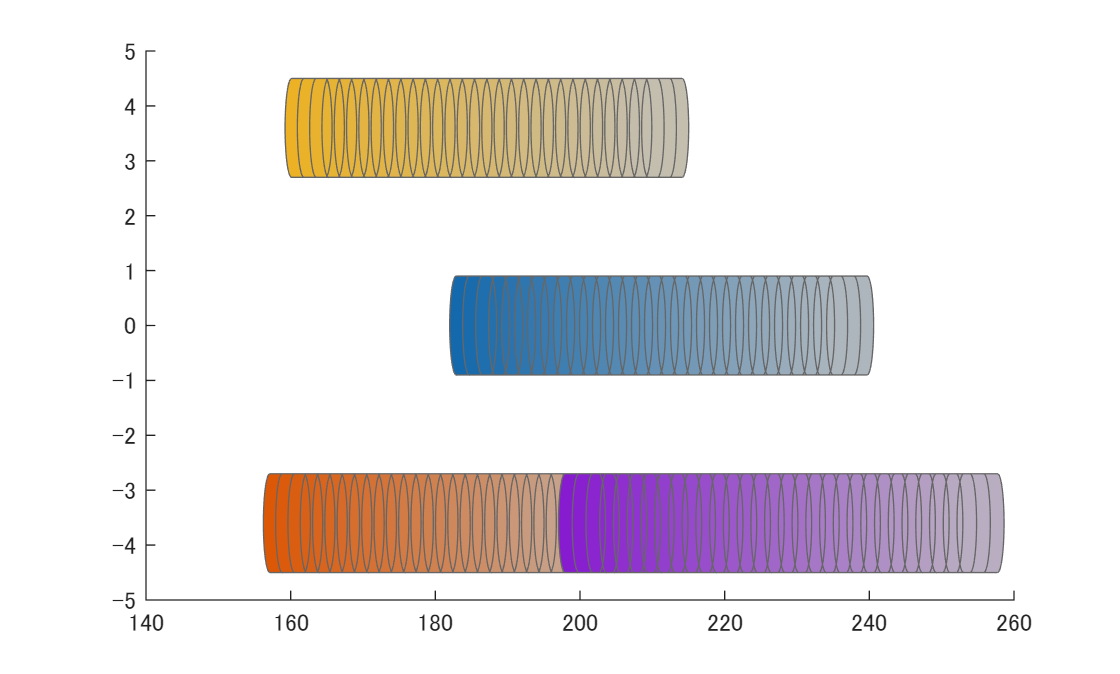

次を使用中のエラー: handle.handle/set
無効であるか削除されたオブジェクトです。

エラー: exampleHelperVisualizeScene (行 22)
        set(lineHandles(1),'XData',traj(:,1),'YData',traj(:,2),'LineStyle',lineStyle,'Color',color,'LineWidth',width);
        ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

    % サンプリングされた軌跡を表示
    lineHandles = exampleHelperVisualizeScene(lineHandles,globalTraj,isValid,trajectoryEvaluation);
    
    hold on;
    show(capList,'TimeStep',1:capList.MaxNumSteps,'FastUpdate',1);
    hold off;
    
    if isempty(optimalTrajectory)
        % すべての軌道は制約条件に違反するか、衝突を引き起こした。
        %
        %   計画が直ちに失敗した場合は、シミュレータ、プランナー、および動作プロパティを再検討してください。
        %
        %  シミュレーションの途中でプランナーが失敗した場合、より複雑な計画条件に対処するために追加の動作を導入できる。
        error('No valid trajectory has been found.');
    else
        % 再計画の間の場面を視覚化する。
        for i = (2+(0:(stepPerUpdate-1)))
            % おおよそのリアルタイム可視化。
            dt = toc;
            if scenario.SampleTime-dt > 0
                pause(scenario.SampleTime-dt);
            end
            
            egoState = optimalTrajectory(i,:);
            scenarioViewer.Actors(1).Position(1:2) = egoState(1:2);
            scenarioViewer.Actors(1).Velocity(1:2) = [cos(egoState(3)) sin(egoState(3))]*egoState(5);
            scenarioViewer.Actors(1).Yaw = egoState(3)*180/pi;
            scenarioViewer.Actors(1).AngularVelocity(3) = egoState(4)*egoState(5);
            
            % カプセルの可視化を更新
            hold on;
            show(capList,'TimeStep',i:capList.MaxNumSteps,'FastUpdate',1);
            hold off;
            
            % ドライビングシナリオの更新
            advance(scenarioViewer);
            tic;
        end
    end
end

## プランナーのカスタマイズと追加の検討事項

カスタムソリューションには多くの調整可能なパラメータが含まれることが多く、それぞれが最終的な動作を予測困難な方法で変化させる可能性があります。本節では、機能固有の特性とそれらが上記のプランナーに及ぼす影響をいくつか取り上げます。その後、カスタムロジックを調整または拡張する方法に関する提案を行います。

### 動的カプセルリスト

前述の通り、`dynamicCapsuleList`オブジェクトは一時的なデータベースとして機能し、予測された障害物の軌道を格納します。これにより、一定時間範囲にわたって1つ以上の自己ボディとの衝突判定を実行できます。`MaxNumSteps`プロパティは、オブジェクトがチェックする時間ステップの総数を決定します。上記のシミュレーションループでは、このプロパティは31に設定されていました。この値は、プランナーが（0.1秒ごとにサンプリングされた）あらゆる軌道の1～3秒間の全期間をチェックすることを意味します。では、`timeHorizons`内の最大値を増やしてみましょう：

timeHorizons   = 1:5; % in seconds
maxTimeHorizon = max(timeHorizons); % in seconds

二つの選択しが存在

- `MaxNumSteps`プロパティは変更されない

- `MaxNumSteps`プロパティは、新しい最大時間間隔に対応するよう更新される

プロパティを変更しない場合、カプセルリストは各軌道の最初の3秒間のみを検証する。計算効率が最優先される場合や予測の確実性が急速に低下する場合に、この方式が望ましい可能性がある。

あるいは、真値データ（上記のように）を使用している場合や、環境の将来状態が完全に把握されている場合（例：集中制御による完全自動化環境）もある。この例ではアクターに対して真値データを使用しているため、プロパティを更新する。

capList.MaxNumSteps = 1+floor(maxTimeHorizon/scenario.SampleTime);

リストのもう一つの間接的に調整可能な特性はカプセル形状である。半径を増加させることで自己車両やアクターの形状を膨張させることができ、`Length`や`FixedTransform`プロパティを変更することで車両に緩衝領域を追加できる。

半径を拡大させることで、エゴビークルの全接地面積を拡大する。

egoGeom.Geometry.Radius = laneWidth/2; % [m]
updateEgoGeometry(capList,egoID,egoGeom);


すべてのアクターに前部と後部の緩衝領域を追加する。

actorGeom(1).Geometry.Length = carLen*1.5; % [m]
actorGeom(1).Geometry.FixedTransform(1,end) = -actorGeom(1).Geometry.Length*rearAxleRatio; % in meters
actorGeom = repmat(actorGeom(1),5,1);
updateObstacleGeometry(capList,actorID,actorGeom);

## 更新されたプロパティでシミュレーションを再実行

シミュレーションを再実行してください。その結果として得られたシミュレーションには、いくつかの興味深い展開が見られます：

- より長い5秒の時間枠により、運転体験は大幅に滑らかになる．プランナーは負の`timeWeight`のため、依然としてより長い軌道を優先する。

- 更新された`MaxNumSteps`プロパティにより、全軌跡にわたる衝突チェックが可能になりました。より長い計画地平線と組み合わせることで、プランナーは以前最適とされた左車線変更を識別して破棄し、元の車線に戻ります

- 膨張したカプセルは早期に衝突を検知し軌道を拒否するため、より保守的な走行行動が生じる。これに伴う潜在的な欠点は計画領域の縮小であり、計画者が有効な軌道を見つけられないリスクを伴う。

% % シミュレータを初期化し、chasePlotビューアを作成する。
% [scenarioViewer,futureTrajectory,actorID,actorPoses,egoID,egoPoses,stepPerUpdate,egoState,isRunning,lineHandles] = ...
%     exampleHelperInitializeSimulator(scenario,capList,refPath,laneWidth,replanRate,carLen);
% tic;
% while isRunning
%     % アクター車両の現在の状態とプラニングホライズン内における軌跡を取得する。
%     [curActorState,futureTrajectory,isRunning] = exampleHelperRetrieveActorGroundTruth(...
%         scenario,futureTrajectory,replanRate,maxHorizon);
% 
%     % 巡航制御の状態の生成
%     [termStatesCC,timesCC] = exampleHelperBasicCruiseControl(...
%         refPath,laneWidth,egoState,speedLimit,timeHorizons);
% 
%     % 車線変更の状態の生成
%     [termStatesLC,timesLC] = exampleHelperBasicLaneChange(...
%         refPath,laneWidth,egoState,timeHorizons);
% 
%     % 前方車追従の状態の生成
%     [termStatesF,timesF] = exampleHelperBasicLeadVehicleFollow(...
%         refPath,laneWidth,safetyGap,egoState,curActorState,timeHorizons);
% 
%     % 終端状態と時間を組み合わせる。
%     allTS = [termStatesCC; termStatesLC; termStatesF];
%     allDT = [timesCC; timesLC; timesF];
%     numTS = [numel(timesCC); numel(timesLC); numel(timesF)];
% 
%     % すべての終端状態のコストを評価する。
%     costTS = exampleHelperEvaluateTSCost(allTS,allDT,laneWidth,speedLimit, ...
%         speedWeight,latDevWeight,timeWeight);
% 
%     % 軌道の生成
%     egoFrenetState = global2frenet(refPath,egoState);
%     [frenetTraj,globalTraj] = connect(connector,egoFrenetState,allTS,allDT);
% 
%     % 制約を違反した軌道の除去
%     isValid = exampleHelperEvaluateTrajectory(...
%         globalTraj, maxAcceleration, maxCurvature, minVelocity);
% 
%     % シーン内の全アクターの予測軌跡を用いて衝突チェッカーを更新する。
%     for i = 1:numel(actorPoses)
%         actorPoses(i).States = futureTrajectory(i).Trajectory(:,1:3);
%     end
%     updateObstaclePose(capList, actorID, actorPoses);
% 
%     % 評価順序を決定する。
%     [cost, idx] = sort(costTS);
%     optimalTrajectory = [];
% 
%     trajectoryEvaluation = nan(numel(isValid),1);
% 
%     % 最小コストから順に、各軌道の衝突をチェックする。
%     for i = 1:numel(idx)
%         if isValid(idx(i))
%             % エゴオブジェクトの候補軌道でカプセルリストを更新する。
%             egoPoses.States = globalTraj(idx(i)).Trajectory(:,1:3);
%             updateEgoPose(capList, egoID, egoPoses);
% 
%             % 衝突のチェック
%             isColliding = checkCollision(capList);
% 
%             if all(~isColliding)
%                 % 衝突が検出されなければ、これが最適な軌道となる。
%                 trajectoryEvaluation(idx(i)) = 1;
%                 optimalTrajectory = globalTraj(idx(i)).Trajectory;
%                 break;
%             else
%                 trajectoryEvaluation(idx(i)) = 0;
%             end
%         end
%     end
% 
%     % サンプリングされた軌跡を表示する。
%     lineHandles = exampleHelperVisualizeScene(lineHandles, globalTraj, isValid, trajectoryEvaluation);
% 
%     if isempty(optimalTrajectory)
%         % すべての軌道は制約条件に違反するか、衝突を引き起こした。
%         %
%         % 計画が直ちに失敗した場合は、シミュレータ、プランナー、および動作プロパティを再検討してください。
%         %
%         %    シミュレーションの途中でプランナーが失敗した場合、より複雑な計画条件に対処するために追加の動作を導入できる。
%         error('No valid trajectory has been found.');
%     else
%         % 再計画の間の状況を視覚化する。
%         for i = (2+(0:(stepPerUpdate-1)))
%             % おおよそのリアルタイム可視化。
%             dt = toc;
%             if scenario.SampleTime-dt > 0
%                 pause(scenario.SampleTime-dt);
%             end
% 
%             egoState = optimalTrajectory(i,:); % [x, y, θ, κ, v] が入っている
%             scenarioViewer.Actors(1).Position(1:2) = egoState(1:2); 
%                                     % Ego 車両の 位置 (x,y) を更新
%                                     % egoState(1) → X座標
%                                     % egoState(2) → Y座標
%             scenarioViewer.Actors(1).Velocity(1:2) = [cos(egoState(3)) sin(egoState(3))]*egoState(5); 
%                                     % Ego 車両の 速度ベクトル (Vx, Vy) を更新
%                                     % egoState(3) = ヨー角 θ [rad]
%                                     % egoState(5) = 速度 v [m/s]
%                                     % [cosθ, sinθ]*v → 進行方向に沿った速度ベクトル
%             scenarioViewer.Actors(1).Yaw = egoState(3)*180/pi;
%                                     % Ego 車両の ヨー角 (向き) を更新
%                                     % egoState(3) はラジアンなので、可視化用に 度 (deg) に変換して代入
%             scenarioViewer.Actors(1).AngularVelocity(3) = egoState(4)*egoState(5);
%                                     % Ego 車両の 角速度 ωz [rad/s] を更新
%                                     % egoState(4) = 曲率 κ = 1/R [1/m]
%                                     % egoState(5) = 速度 v [m/s]
%                                     % 曲率と速度の関係：𝜔 = 𝑣 ⋅ 𝜅
%                                     % → 半径 R のカーブを速度 v で走ると角速度は 𝑣/𝑅
%                                     % それを egoState(4)*egoState(5) で表現している
% 
%             % カプセルの可視化を更新する。
%             hold on;
%             show(capList,'TimeStep',i:capList.MaxNumSteps,'FastUpdate',1);
%             hold off;
% 
%             % ドライビングシナリオの更新
%             advance(scenarioViewer);
%             tic;
%         end
%     end
% end

*Copyright 2020 The MathWorks, Inc.*